# DiD Toolbox Documentation: Tools for Difference-in-Differences Analysis

   **Ralf Elsas-Nicolle (LMU Munich, Germany,  Version as of 01/26/2026)**

## I General Overview of Purpose, Structure, and Implementation

#### Purpose

The DiD Toolbox is a set of Matlab tools designed for applied statisticians and econometricians to conduct Difference-in-Differences (DiD) analyses, particularly focusing on designs involving staggered treatment timing. The traditional Two-Way Fixed Effects (TWFE) estimator, while common, yields estimates that may be biased and difficult to interpret when treatment effects are heterogeneous across groups or vary over time. The primary goal of this toolbox is to address these methodological challenges by providing modern, robust estimators that yield valid causal estimates in complex multi-period, staggered adoption scenarios.

#### **Disclaimer**

- `The toolbox is under development.`

- `I backtested all of the estimators and corresponding results using simulated data with Stata 18, utilizing implementations by Stata Corp. itself and some of the packages designed by the underlying paper's authors. Also see the provided example file, which has a Stata log-file for comparison. `

- `A full list of the current worked examples shipped with the Toolbox is in the Appendix. `

- `All implemented estimators have been tested for unbiasedness of point estimates and standard errors via Monte Carlo-simulation. `

- `Most of the code base was developed with the help of ChatGPT 5 Thinking, Gemini 3 Pro, and Matlab MCP-Server.  `

`If researchers with interest in the topic and OOP skills in Matlab are interested in joining this project, I'd very much appreciate collaboration.`

#### Overview Codebase and Theoretical Foundations

The methodologies of the toolbox are grounded in foundational and recent academic literature. The software implementation uses Object-Oriented Programming (OOP) within Matlab.

**Theoretical Papers**: The toolbox implements in particular methods developed or discussed in the following key papers:

- Goodman-Bacon (2021): Provides the mathematical foundation for the decomposition of the TWFE estimator, explaining how it operates as a weighted average of DiD estimates and identifying the source of bias from "negative weights" due to treatment effect heterogeneity.

- Wooldridge (2021): Establishes the algebraic equivalence between the Two-Way Fixed Effects (TWFE) estimator and the Two-Way Mundlak (TWM) regression, enabling flexible implementation using pooled OLS.

- Borusyak, Jaravel, and Spiess (2024): Derives the efficient and robust imputation estimator (BJS) for staggered DiD, which estimates counterfactual outcomes using only untreated observations to calculate heterogeneous causal effects, providing efficiency and avoiding spurious identification.

- de Chaisemartin and D'Haultfœuille (2020): Proposes the $$DID_M$$ estimator, which estimates a robust Average Treatment Effect across switching cells ($$\delta_S$$) and introduces robustness measures for assessing TWFE bias, particularly in designs where weights may be negative. And the unique feature is that the estimator can handle an on/off treatment, while all other estimators assume that treatment is an absorptive state.

- Callaway / Sant'Anna (2021): CS focus on cohort/time based analyses, looking at $ATT(g,k)$ with a focus on taking covariates into account. They derive identification, estimation, and inference strategies assuming parametric nuisance models (i.e. linear outcome regression, logit for propensity scores) that admit standard regularity conditions. In an extension, the interaction weighted estimator by Sun/Abraham (2021) builds on this work, showing how get unbiased event studies in this setting. 

- Rambachan/Roth (2023):The study suggests a sensitivity analysis for the parallel trends assumption of DiD analyses by asking “*how large could a violation be before our conclusion changes?*” They propose bounding the treatment effect estimates under various degrees of pre-trend differences.

- Arkhangelsky et al. (2021): The study discusses synthetic difference-in-differences (SDID) methods, which try to generate parallel trends by reweighting units to match their pre-exposure trends.

**Codebase Structure**: The Matlab source code utilizes OOP principles under the +did/ package namespace:

- *Core Classes and Functions*: fit.m, Model.m (orchestration), getEstimator.m, Dataset.m (data management).

- *Utilities*: descData.m (descriptive statistics for DiD data), genDIDdata.m (simulation utility) and others.

- *Estimation Modules*: Specific estimators are located in the +did/+estimators/ folder, including implementations for the *de Chaisemartin/d'Haultfœuille* estimator (ch_estimator.m), *Borusyak/Jaravel/Spiess* (BJS) estimator (bjs_imputation.m), *Wooldridge* (TWM) estimator (wooldridge_TB.m) as well as *Callaway/Sant'Anna* (cs_estimator.m) with the extension of interaction weighing by *Sun/Abraham *(iw_estimator.m).

- Covariance Estimation: The +did/+vcov/ package handles various variance-covariance strategies, including WildBootstrap.m and Clustered.m.

#### Usage lllustrations

The toolbox provides several illustrations on how to use it, available as in the folder "Examples":

- *SimpleDIDAnalysis.mlx*: A simple live script, covering the basics of 2x2 DiD.

- *RealWorld_Example_DiDToolbox.mlx* (with a complementary Stata 18 log-file, analyzing the same data for comparison).

- A blog post on some backtesting of the estimators' implementation via Monte Carlo-simulation can be found [here](https://ralfelsas.de/did-toolbox-for-matlab/).

See the **Appendix **for a full list of included examples.

## II Description of Different Tools for Analysis

### II.0    General

Throughout the toolbox, data is described by four key variables:

The function requires a panel data table (T) and mandatory name-value arguments for identifying necessary items for conducting DiD analyses (*idVar*, *timeVar*, *dVar*).

- Input data table (*T*)

- *idVar*: Identifier for units in the panel data

- *timeVar*: Time indicator

- *dVar*: Identifier per individual and time point whether treated or not (dummy)

When using commands, these are the names of input field (except for *T*), where you provide in the function call the actual (and potentially different) names of items in your data (e.g. timeVar="t"). 

You should start your analysis of data T by instantiating a validated  data object, similar to the following:

    *ds = did.Dataset.fromTable(T, idVar="id", timeVar="time", dVar="D", yVar="y",describe=true);  *

The typical command to conduct estimations then is called using *did.fit(ds,options)*

All functionality can also be called by using the full syntax similar to the following:

    *resWool =  did.fit("Wooldridge", T, idVar="id", timeVar="time", dVar="D", yVar="y",options);*

but the recommended proceeding is by using a data object.

There are three exceptions:

- Generating simulated panel data with or without different forms of treatment using* did.genDIDdata(.)*

- *did.Dataset.fromTable(.) i*s the first initiation of the data object and thus requires the definition of the data table and the key variables' names.

- The only command that is estimator specific is a plotting utility. It needs to be called based on an estimator's output (instead of the data object *ds*),:

            d*id.did_plot(resWool, "event");       % event-study*

### II.1    Simulating data

For understanding and backtesting the estimators in this toolbox (or DiD settings in general), genDIDdata.m generates data suitable for DiD analyses. It generates the outcome variable by combining components such as the base outcome (`y_base`), factoring in influences from time-varying covariates (y`X`), the true treatment effect (`tau_true`), and an error term (`epsilon`). You can set the number of individuals, how many are treated and what are the treatment effects and their time patterns.

#### Syntax

**Mandatory:*** numPeriods*, *numIds* and *percTreated *are mandatory input arguments and shall be directly provided in this order.  

The function supports different characteristics of  the treatment effects:

   ** treatType**="constant"|"constantTime"|"timeIncrease"|"onOff"

- Type "*constant*": The canonical DiD type, where all treatments have the same magnitude and happen at the same time (over time and over cohorts).

- Type "*constantTime*": Treatment is staggered, numCohort is the number of cohorts (with different start of treatment), *CohortIncrease* is the difference in ATT per cohort / first treatment time.

- Type " *timeIncrease*" increases the treatment effect within cohort over time after first treatment (*dynEffect* gives the change per period)

- Type "*onOff*" generates non-absorptive treatment, ending in *endPeriod* (a vector with length equal to *numCohorts*)

**Cohorts** can be explicitly set w.r.t *CohortTimes* (timing of treatment start), *CohortSize* (absolute size of each cohort) or *CohortProbs* (fraction of each cohort (vector length of *cohortProbs *must equal number of cohorts)

**Syntax illustration for different use cases**

Also see the Example_GenDID_Showcase.m in the ./Examples folder for an illsutration of all availbale cases. This script runs 7 different scenarios to illustrate the versatility of genDIDdata:

- *Basic*: Standard setup with constant ATT and no staggered treatment.

- *Dynamic Effects*: Effects growing over time (treatType="timeIncrease").

- *On/Off Treatment*: Reversible treatment (treatType="onOff").

- *Explicit Cohorts*: Block assignment design (cohortTimes=[...]).

- *Divergent Controls )(SDID)*: Bias injection where a share of controls violates parallel trends.

- *Unit Trends*: Random unit-specific time slopes.

- *Selection Bias*: Treatment probability driven by covariates ($X$).  

**Basic Usage**: Canonical DID (2x2): Standard setup with a single treatment onset (`startPeriod`) and parallel trends.

% N=500 units, T=10 periods, 40% treated
% Treatment starts at T=5 for all treated units

% T = did.genDIDdata(10, 500, 0.4, 'treatType',   "constant", 'startPeriod', 5, 'ATT',  2.0);

**Staggered Adoption (Random)**: Treatment timing is randomized across a window (`startPeriod` to `endPeriod`). Use `treatType = "constantTime"` for a constant effect after adoption.

% Treated units adopt randomly between T=3 and T=8

% T = did.genDIDdata(10, 500, 0.4, 'treatType',   "constantTime", 'startPeriod', 3, 'endPeriod',   8, 'ATT', 2.0);

**Staggered Adoption (Cohorts): **Deterministic cohorts with specific adoption times (`cohortTimes`).

% 3 Cohorts adapting at T=3, T=5, T=7

% T = did.genDIDdata(10, 500, 0.4, 'treatType',"constantTime", 'cohortTimes', [3, 5, 7], 'ATT', 2.0);

**Selection Bias & Confounding Trends (CEM Scenario)**

Generates data where:

- Selection Bias: Units with higher *X* are more likely to be treated.

- Confounding Trend: *X* drives a linear time trend (violating parallel trends if uncontrolled).

- Note: Requires *xNum > 0 *(i,e, at least one covariate to be generated).

% Selection on X1 and Trend driven by X1

% T = did.genDIDdata(10, 500, 0.4,  'xNum', 1, 'SelectionBias', 1.0, ...     % High X -> Higher Prob(Treat)
%     'TrendEffectX',  0.5, ...     % Y increases with X*Time
%     'ATT',           2.0);

**Dynamic Treatment Effects: **Effect grows over time after adoption $\Theta_t$.

% Base effect = 1.0, grows by 0.5 per period after adoption

% T = did.genDIDdata(10, 500, 0.4, 'treatType',   "timeIncrease", 'startPeriod', 5, 'ATT',  1.0, 'dynEffect',   0.5);

**On-Off Treatment (Transient):  **Treatment turns on at `startPeriod` and off at `endPeriod`.

% Treatment active only between T=4 and T=7

% T = did.genDIDdata(10, 500, 0.4, 'treatType',   "onOff", 'startPeriod', 4, 'endPeriod',   7, 'ATT', 2.0);

**Divergent Controls (SDID):** Synthetic DiD can help to improve a DiD analysis by weighting individuals of the control group and time-periods to better achieve parallels trends. For simulating corresponding data use the following parameters:

- preTrendType="divergentControls" 

- preTrendMeanTreated = #number (slope treated)

- preTrendMeanControl = #number (for the divergent control)

- preTrendDivergentShare = fraction (fraction of controls with divergent trend)

% Generate controls with divergent trends (80% of controls, trend 0.5 vs -0.2 for divergent units) 
% data = did.genDIDdata(T_len, N, N_treated/N, ...
 %        "ATT", TrueEffect, ...
 %        "treatType", "constantTime", ...
 %        "cohortTimes", cohortTimes, ...
 %        "meanError", 0, "errorStd", 1.0, ...
 %        "preTrendType", "divergentControls", ...
 %        "preTrendMeanTreated", 0.5, ...
 %        "preTrendMeanControl", -0.2, ...
 %        "preTrendSd", 0.5,...
 %        "preTrendDivergentShare", 0.8); 

#### **Worked Example**

    clear;
    T = did.genDIDdata(12, 500, 0.6, ...
        treatType="constantTime", startPeriod=4, ...
        cohortTimes=[4 7 10],xNum=2,                     ... % creates x1, x2
        betaX=[0.6, -0.4],          ... % effect of x1,x2 on y
        xUnitStd=1, xTimeStd=1, xShockStd=1, CohortIncrease=1);

    % Instantiate data object:
    ds = did.Dataset.fromTable(T, idVar="id", timeVar="time", dVar="D", yVar="y",describe=true);  


[DataDesc] Units = 500 | Periods = 12 | Nobs = 6000 | Balanced Units = 500 (100.0%)
[DataDesc] Ever-treated = 297 (59.4%) | Never-treated = 203 (40.6%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "4"            80       0.16        0                   0                      4       
        "7"           105       0.21        0                   0                      7       
        "10"          112      0.224        0                   0                     10       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean 

**Note**: In this example, the true treatment effects are set to 2, 3.5 and 5 for the cohorts treated at time 4,7, and 10, respectively. As we know the true $$ATT(g,t)$$ in the simulated data, this allows to compare the estimated coefficients between different methods under the same degrees of data characteristics (like covariates, error term variance etc.).

#### **Output**

Key variables in the generated data table are the identifier items *id* (idVar),* time* (timeVar), *y* (yVar) and *D* (dVar), where the latter is the indicator variable for actual treatment.

### II.2    Data Description Utility

The *did.dataDesc* function provides a quick overview of the panel dataset, summarizing essential characteristics such as unit counts, time periods, treatment assignment patterns, and outcome variable descriptives.

This utility calculates descriptive statistics by identifying the panel structure, determining treatment cohorts based on their first treatment date, and classifying units as ever-treated, never-treated, or "leavers" (units whose treatment turned off after being on). If an outcome variable is provided (yVar), overall and cohort-stratified descriptive statistics are computed.

Note that it is automatically called when instantiating the data object with the option *describe=true*

#### Syntax

The function requires the panel data table (T) and mandatory name-value arguments for identifying columns (*idVar*, t*imeVar*, *dVar*).

Example

descStat = did.dataDesc(ds);


[DataDesc] Units = 500 | Periods = 12 | Nobs = 6000 | Balanced Units = 500 (100.0%)
[DataDesc] Ever-treated = 305 (61.0%) | Never-treated = 195 (39.0%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "4"           112      0.224        0                   0                      4       
        "7"           101      0.202        0                   0                      7       
        "10"           92      0.184        0                   0                     10       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean 

#### Output

- *Overview*( table): Summarizes time range, #periods, #units, $$N_{obs}$$, balance, EverTreated, NeverTreated, and Leavers.

- *Cohorts* (table): Details on treatment cohorts (first treat time), including unit counts and leaver statistics per cohort.

- *PeriodStats* (table): Statistics by time period (units observed, treated, not-yet, never, off-after-on).

- *Y_overall* (table): If yVar is provided, overall summary statistics (N, Mean, SD, Min, Median, Max).

- *Y_by_cohort* (table): If yVar is provided, summary statistics broken down by treatment cohort (including the "never" treated group) are included.

- Options (table): Identifiers provided

### II.3    Plotting Utility

For convenience, a plotting utility *did_plot* is provided. After running an estimator of the toolbox (see the next section), one can easily make graphs of treatment effects, either aggregated over cohorts ("cohort") or over event time ("event"). Some functionality automatically produces plots under the (default) option *Display=true*.

**1. General Plotting (**`did_plot.m`**)**

The main entry point is  `did_plot(res, type, ...)`.

- `"event"`: Plots event-study estimates (`ATT(e)` vs Event Time). Supports error bars or confidence bands.

- `"cohort"`: Plots estimates by cohort.

-         If `chCohortLines` exist: Plots `DID+` and `DID-` lines.

-         Otherwise: Plots point estimates/SEs per cohort.

- `"calendar"`: Plots calendar-time estimates (`ATT(t)`).

- `"support"`: Visualizes support (e.g., number of observations or cohorts per event time).

- `"trends"`: Plots raw outcome trends for treated cohorts vs. never-treated. Requires passing a `did.Dataset` object directly.

- Options: `Alpha`(CI level), `Legend`, `ZeroLine,Labels`

**2. Sensitivity Analysis (**`+diagnostics/HonestDiD.m`**)**

- `HonestDiD.plot(res)`: Visualizes sensitivity analysis results (Rambachan & Roth).

- Plots the "Original Estimate".

- Shows the Identified Set (dark gray) and Confidence Interval (light gray) across a range of sensitivity parameters ($M$).

**3. Synthetic DiD (**`+estimators/SDID.m`**)**

- `did.estimators.SDID.plot(res)`: produces a dashboard with 3 panels:

- Trends: Treated vs. Synthetic Control outcome history.

- Gap: Difference between Treated and Synthetic Control (the treatment effect path).

- Weights: Bar chart of the top control unit weights.

#### Syntax

   * did.did_plot(resBJS, "cohort")*

#### Example

resWool =  did.fit("Wooldridge", ds, Covariates=["x1","x2"]);

[wooldridge] ATT by cohort (mean of cohorts coefficients):
    Cohort    #TimePeriods    Estimate       SE       tStat       pValue   
    ______    ____________    ________    ________    ______    ___________

       4           9           2.0826      0.10339    20.144     1.7558e-66
       7           6            2.994     0.098557    30.378    1.5358e-115
      10           3            3.857      0.12077    31.936    1.0552e-122

[wooldridge] Overall ATT (cohort-share weighted):
    Estimate      SE       tStat       pValue   
    ________    _______    ______    ___________

     2.634      0.07462    35.298    9.4758e-138

[wooldridge] ATT by 

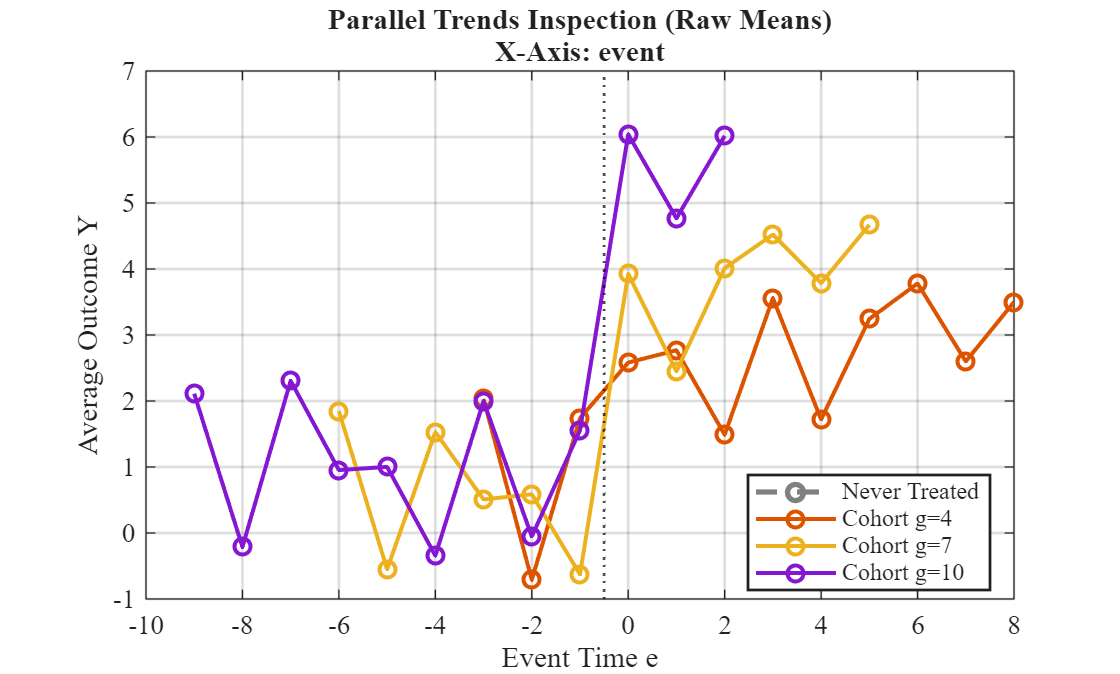

% plotting estimated event time coefficients
did.did_plot(resWool,"event");
% fprintf('Plotting raw trends (Calendar Time)...\n');
did.did_plot(ds, "trends", 'Legend', true);

% fprintf('Plotting raw trends (Event Time)...\n');
did.did_plot(ds, "trends", 'XAxis', "event", 'Legend', true);

### II.3    Diagnostic Tool: Bacon Decomposition

The Bacon Decomposition, based on the work of Goodman-Bacon (2021), is a necessary diagnostic tool in staggered DiD settings. The standard TWFE estimator $$\hat{\beta}_{DD}$$ is shown to be a weighted average of all possible Difference-in-Differences (DD) estimators based on the cohorts in the data. The decomposition identifies the contribution of four types of comparisons:

- Treated vs. Untreated: Compares a treated cohort to a never-treated control group.

- Early vs. Late Treated (Admissible Timing): Earlier-treated groups act as treatment, later-treated groups act as controls during their pre-period.

- Late vs. Early Treated (Forbidden Comparison): Later-treated groups act as treatment, already-treated earlier groups act as controls.

#### Role of Negative Weights

When Average Treatment Effects (ATT) vary over time ($$\Delta ATT \neq 0$$), the "Late vs. Early" (forbidden) comparisons are the primary source of negative weights. This occurs because the TWFE specification implicitly uses already-treated units as controls for later-treated units, causing changes in the outcomes of the already-treated group (which include changes in their treatment effects) to be subtracted, biasing the estimate away from the desired causal parameter (VWATT). If treatment effects are constant, weights are positive.

#### Syntax Example

res = did.fit("bacon", T, idVar="id",timeVar="time",yVar="y",dVar="D");

**Output** comprises

- *res.ByType* (aggregated decomposition) and 

- *res.Pairs *(pairwise comparisons)

Example:

res = did.fit("bacon", ds);


---- Bacon: Overall (TWFE) -----
    2.9399

Bacon: ---- Comparisons -----
               type               group1    group2     weight     estimate
    __________________________    ______    ______    ________    ________

    "Treated vs Never Treated"       4         0       0.21757     2.1669 
    "Treated vs Never Treated"       7         0        0.2616     3.0254 
    "Treated vs Never Treated"      10         0       0.17872     3.8175 
    "Treated earlier vs later"       4         7      0.037563     2.0452 
    "Treated earlier vs later"       4        10      0.068431     2.0889 
    "Treated earlier vs later"       7        10      0.061711     2.7157 
    "Treated later vs earlier"       7         4      0.075126     2.9513 
    "Treated later vs earlier"      10         4      0.068431     4.0227 
   

## III    Estimator Descriptions and Syntax

The toolbox provides implementations for the standard TWFE estimator and five robust estimators designed for staggered adoption settings.

Default for **standard errors** is always *idVar*, unless the specific estimator requires a specific method. If you want other clustering options, you have to set "vcov"= *clusterMethod*. If clustering on one or two specific variables is desired, set "clusters" (e.g. ["id", "time"]).

### III.1    Two-Way Fixed Effects (TWFE)

#### Estimation Strategy

This method fits a linear regression model using Ordinary Least Squares (OLS) including full sets of unit fixed effects ($$\alpha_i$$) and time period fixed effects ($$\beta_t$$): $$$Y_{it} = \alpha_i + \beta_t + \tau D_{it} + \epsilon_{it} \quad$$$

The estimate $$\hat{\tau}_{FE}$$ is numerically the same as the coefficient obtained from the Two-Way Mundlak (TWM) regression without covariates. 

You can add covariates by providing their item-name in the data table when calling the estimator by setting, e.g., *Covariates=["x1","x2"] .*

TWFE estimates the fixed-effects using absorption, so that demeaning of individual and time effects is conducted iteratively (. For demeaning, the defaults is *absorbMethod='halprin'*, using the product of the projection matrices.Alternatively,  *absorbMethod='cimmino'*  utilizes means of the projection matrices. This implementation is similar to Stata 18. You can check on convergence details by setting the parameter *details=true*.

If you use a very large set of you can also set *absorbUseGPU=true* (default is false), for fast estimation.    

#### Use Case & Caveat 

TWFE was until recently the standard for DiD analyses, but in staggered designs with heterogeneous effects, $$\hat{\tau}_{FE}$$ identifies a variance-weighted average treatment effect on the treated plus bias terms. If negative weights occur, or weights of "forbidden" comparisons (with already treated groups) are substantial, the estimate can be misleading.

Quite generally speaking, if treatment is staggered, potentially differs between cohorts, or is an on/off treatment, use the Bacon decomposition to analyze heterogeneous treatment effects of cohorts, and if it is indicated, use *BJS*, *Wooldridge* or $DID_M$ estimator (the choice depends on your use case, see the estimators' descriptions).

#### Syntax Example 

res = did.fit("twfe", T, idVar="id",timeVar="time",yVar="y",dVar="D", vcov="clustered", clusters=["id","time"]);

#### Output

The function returns only the coefficient for the interaction isTreatmentGroup * isTreated and coefficients on covariates, if provided. 

Example

res = did.fit("twfe", ds, Covariates=["x1","x2"],...
               vcov="clustered", clusters=["id","time"]);

[TWFE] DepVar: y
[TWFE] Obs: 6000 | Units: 500 | Time: 12
[TWFE] Within-R2: 0.3559
[TWFE] Fixed Effects: Unit, Time
[TWFE] Standard errors clustered by id, time 
  3×5 table

    Name    Estimate       SE        tStat       pValue  
    ____    ________    ________    _______    __________

    "D"       2.9638     0.18122     16.355     4.571e-09
    "x1"     0.61235    0.017023     35.973    9.2194e-13
    "x2"    -0.39613    0.024458    -16.197    5.0677e-09



### III.2    Flexible Estimator: Wooldridge (TWM)

#### Estimation Strategy

This estimator uses the algebraic equivalence of the TWFE estimator and the Two-Way Mundlak (TWM) regression. The TWM regression is a pooled OLS regression that includes the time-varying covariates, unit-specific time averages ($$\bar{x}{i.}$$) and period-specific cross-sectional averages ($$\bar{x}{.t}$$). The key is that the two-way fixed effects estimate ($$\hat{\mathbf{\beta}}_{FE}$$) is identical to the coefficient on $$x_{it}$$ obtained from the TWM regression ($$\hat{\mathbf{\beta}}_M$$).

This equivalence simplifies modeling complex heterogeneity (e.g., cohort-specific TEs, time-varying effects, and flexible covariate interactions), allowing the user to implement highly flexible versions of TWFE using the computational simplicity of pooled OLS. In the staggered case, the approach can be used to identify cohort/calendar time combinations that have causal interpretations.

Standard errors are clustered by the option *clusters*. Stata uses clustering on the cohort level (then use a variable that identifies the cohorts, e.g. *clusters="gvar"*). Alternatively, one could use clustering on the individuals level (i.e. use e.g. *clusters="id"*). 

The control group for the treated observations are the never treated observations. If these don't exist, the last treated cohort is omitted and used as control for the other cohorts. 

#### Syntax:

res = did.fit("wooldridge", T, idVar="id",timeVar="time",yVar="y",dVar="D", vcov="clustered", clusters="id");

or 

res = did.fit("wooldridge", ds, vcov="clustered", clusters="id");

#### Output

- Overall ATT

- ATT by time

- ATT by event time

- If you set the option *details,* the full regression output with the pairwise estimates is shown

Example

res = did.fit("wooldridge", ds, Covariates=["x1","x2"],vcov="clustered", clusters=["id"]);

[wooldridge] ATT by cohort (mean of cohorts coefficients):
    Cohort    #TimePeriods    Estimate       SE       tStat       pValue   
    ______    ____________    ________    ________    ______    ___________

       4           9           2.0826      0.10339    20.144     1.7558e-66
       7           6            2.994     0.098557    30.378    1.5358e-115
      10           3            3.857      0.12077    31.936    1.0552e-122

[wooldridge] Overall ATT (cohort-share weighted):
    Estimate      SE       tStat       pValue   
    ________    _______    ______    ___________

     2.634      0.07462    35.298    9.4758e-138

[wooldridge] ATT by 

### III.3    Robust/Efficient Estimator: Borusyak, Jaravel, Spiess (BJS)

#### Estimation Strategy 

BJS provides the efficient linear unbiased estimator for estimating pre-specified weighted sums of treatment effects ($$\tau_w$$) in staggered designs, allowing for unrestricted heterogeneity ($$\mathbf{\Gamma} = \mathbf{I}$$). The procedure is intuitive:

    1. Fixed Effect Estimation: Estimate unit ($$\hat{\lambda}_i^$$) and period fixed effects ($$\hat{\delta}^$$) using OLS applied only to the untreated observations ($$i,t \in \mathcal{I}_0$$).

    2. Imputation: Impute the counterfactual untreated potential outcome ($$\hat{Y}_{it}(0) = \hat{\lambda}_i^* + \hat{\delta}^*$$) for treated observations ($$i,t \in \mathcal{I}_1$$).

    3. Effect Calculation: The estimated treatment effect for each observation is $ $\hat{\tau}{it}^* = Y{it} - \hat{Y}_{it}(0)$$, which are then aggregated by the chosen weights to estimate the target $$\hat{\tau}_w^*$$.

This method is robust, avoids "forbidden comparisons," and is characterized as efficient under spherical errors. It explicitly avoids the spurious identification of long-run causal effects that plagues conventional dynamic TWFE specifications.

- Standard errors are estimated via the jackknife ("leave-one-out", LOO) method as the default.

- If you have many individuals in the panel, you might want to set the optional parameter *useParallel* equal to the number of processors to be used with parallel processing.

- Alternatively, you could use the option *SEMethod = "BootstrapUnit",* which instead of jackknifing (where just one unit is dropped with each bootstrap repetition)  units will be randomly resampled. You can also set *BootReps* to control the number of bootstrap samples to be used. 

#### Syntax

res = did.fit("BJS", T, idVar="id", timeVar="time", yVar="y", dVar="D");

or

res = did.fit("BJS",ds);

#### Output

The output consists of 

- the overall weighted ATT

- one table that shows ATT per cohort, weighted by number of obs cohorts (and s.e., nobs, CI).  

- More output is returned but not printed.

Example:

res = did.fit("BJS",ds, Covariates=["x1","x2"],useParallel=8);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

[BJS Optimized] N_unt=4110, N_trt_ident=1890. Overall ATT: 2.6370 (SE 0.0819)

[BJS] Estimates (SE=LOO, Boot=199)
        Name         Estimate       SE       tStat       pValue   
    _____________    ________    ________    ______    ___________

    "ATT_overall"      2.637     0.081873    32.208    1.3679e-227
    "ATT_k=0"         2.8498      0.11466    24.855    2.3099e-136
    "ATT_k=1"         2.9114      0.11112      26.2    2.6521e-151
    "ATT_k=2"         3.0407      0.11234    27.067    2.4024e-161
    "ATT_k=3"         2.5173      0.13972    18.017     1.4231e-72
    "ATT_k=4"         2.5726      0.13517    19.032     9.2612e-81
    "ATT_k=5"         2.5932      0.14278    18.162     1.0336e-73
 

### III.4    Robust Estimator: de Chaisemartin/D'Haultfœuille Estimator (DID_M)

#### Estimation Strategy 

The DID_M estimator targets $\delta_S$, the Average Treatment Effect (ATE) across all "switching cells"—groups whose treatment status changes between $ $t-1$$ and $$t$$. This is calculated as a weighted average of two specific DiD terms:

    ◦ $$DID_{+,t}$$: Compares joiners (treatment $ $0 \to 1$$) to groups remaining untreated.

    ◦ $$DID_{-,t}$$: Compares leavers (treatment $$1 \to 0$$) to groups remaining treated.

$$DID_M$$ is valid under heterogeneous treatment effects and inherently avoids the source of negative weighting bias by strictly contrasting switching groups against stable groups. In staggered adoption designs, where treatment is typically irreversible,$ $DID_M$ $is a weighted average only of the $$DID_{+,t}$$ estimators.

**Note** 

- Contrary to the TWFE, Wooldridge and BJS estimators, DID_M measures treatment effects only at the period of entry and exit, i.e. not over all periods of treatment. 

- $DID_M$ is the only estimator (to my knowledge) which can handle on/off-treatments. i.e. not assuming that treatment is an absorptive state. 

#### Diagnostic

The Placebo$ $DID_M$$ ($$DID_{M,pl}$$) is computed, comparing pre-switch outcome trends ($$t-2$$ to $$t-1$)$ for switching groups versus stable groups. A significant placebo estimate suggests the parallel trends assumption (Assumptions 4, 5, 9, and 10 in the paper) is violated.

#### Syntax 

resDIDM = did.fit("DID_M", T, idVar="id", timeVar="time", yVar="y", dVar="D");

#### Output

The function returns 

- an overall weighted estimate of the ATT (labeled DID_M) and separate coefficient estimates for "Joiner_Only" and "Leavers_only". I addition, the weighted overall estimate for the placebo test is provided (Placebo_DIDI_M).

- the coefficients for each cohort, differentiated by the period of entry (DID_plus) and end of treatment (DID_minus).

Example:

res = did.fit("DID_M", ds,Covariates=["x1","x2"]);


=== DID_M summary (table) ===
              Effect               Estimate      SE         t           p     
    ___________________________    ________    _______    ______    __________

    "DID_M"                         2.6952     0.15337    17.573    3.6638e-54
    "Joiners-only"                  2.6952     0.15337    17.573    3.6638e-54
    "Leavers-only"                       0           0       NaN           NaN
    "Overall (cohort-weighted)"     2.6952     0.15117    17.829    2.2397e-55
    "Placebo DID_M"                0.19775     0.14146     1.398       0.16275


=== DID_M by Cohort (table) ===
    t     DID_plus    DID_minus
    __    ________    _________

     4     2.136         NaN   
     7     2

### III.5    Callaway / Sant'Anna 2021 (CS)

#### Estimation Strategy

In panels where units adopt at different times (or never), Callaway/Sant’Anna (CS) compute treatment effects for each cohort–time cell, written ATT(g,t): “the average effect at calendar time *t* for the cohort first treated in *g*.” This avoids the mixing issues of classic TWFE when effects vary over time or across cohorts. 

- Groups of comparison are "never" or "notyet" treated. 

- As outcomes can move before formal adoption, you can set Delta = δ ≥ 0 to exclude the δ periods before adoption from the pre-treatment baseline (*Delta*). The baseline becomes r = g − δ − 1 (instead of g − 1).

- Standard errors are estimated by a wild bootstrap type of method (e.g. *SEMethod="multiplier"*) or clustered on the unit level (SEMethod="clustered"). If there is another time-invariant source of heterogeneity between groups of data, a second cluster variable can be used.

Four possible estimation approaches are:

- *unconditional*: no covariates are taken into account (*Approach="unconditional"*).

- *OR*: Outcome regression, not taking control variables into account (*Approach="OR"*). 

- *IPW*: Uses inverse probability weighting for handling the covariates**. **Estimates propensity Pr(G=g | X), reweights controls to match treated covariates, and compares mean changes (*Approach="IPW"*).

- *DR*: Combine OR and IPW (doubly robust), i.e. adjust treated by an outcome model and weight control residuals by propensities. If only one of the two models are corrected, ATT estimates will be unbiased  (*Approach="DR"*). 

Note that with covariates, DR is the recommended option, as Sant'Anna/Zaho (2020) show that even if none of the two approaches are correct, DR still perform better than either of the single model approaches.

#### Aggregations

In a recent paper, Deb et al. (2025) show that Stata's implementation of the CS estimator uses weights for aggregation based on 

- the number of treated observations in cohort $c$ at treated time $t$ ($t>c$), and

- the number of pre-period reference counts for each post cell

Deb et al. (2025) show that this can distort estimation of the overall ATET for repeated cross-sections (and such a weighting was not suggested by CS):

- *Balanced panels***:** no problem - the two formulas coincide because $Nct=Nc,c-1N_{ct}=N_{c,c-1}Nct=Nc,c-1$� for each cohort and time. 

- *Repeated cross-sections with varying cell sizes***:** differences arise because $N_{ct}$ varies over $t$. The Stata weight adds a time-invariant pre-period count to each post cell, changing relative weights across $(c,t)$ 

- *Big pre-period relative to post-period sizes***:** the distortion is largest when the pre-period sample for a cohort is large relative to its post-period sizes. (In their simulation, this pushes more weight onto later post periods and raises the aggregated ATET.) 

- *Heterogeneous effects over cohorts/time***:** the more treatment effects vary across $(c,t)$, the more harmful the wrong weights become; if all ATTs were equal, weighting wouldn’t matter. 

- *Declining treated sample sizes over time*: particularly prone to bigger gaps between the correct and Stata’s aggregation. 

- *Not just “overall”***:** the same weighting issue also affects event-time, by-cohort, and calendar-time averages. 

The DiD Toolbox does not use the counts of pre-period observations for weighting. Instead it offers the options

- *Weighting="treatedObs",* which is the preferred  weighting scheme by Deb et al. (2025) and the default, or alternatively

- *Weighting="cohortShare"*, cohort-share weights that are constant across a cohort’s post-treatment periods.

#### Models with covariates (Sant'Anna/Xu 2025)

When using Outcome Regression (OR), Inverse Probability Weighting (IPW), or Doubly Robust (DR), one is fitting nuisance models:

-   OR: regression of $\Delta Y$ on $X$ for controls

-   IPW: logistic regression for $Pr(G=g|X)$

-   DR: both

If one uses the same sample to both estimate the nuisance functions (regressions / propensity scores) and to plug them into the ATT formula, ones risks overfitting. This bias can be especially bad when:

- $X$ is high-dimensional

- The nuisance models are complex (ML, flexible nonparametrics)

The input parameters *CrossFit *(together with *Kfolds*) uses the kFold estimation by (Chernozhukov et al. 2018, "Double/Debiased ML") to split the sample into *k* folds, where one subsample is held out of the estimation. In the end, ATTs are constructed from recombining the estimates. Setting *StratifyFoldsBy="cohort" *keeps a similar share of each cohort in every fold.

The default for *CrossFit* is *false*, however, as the logistic regression is well behaved in most cases.

#### Syntax

    resCS = did.fit("cs", ds, ...
               Comparison="never", Delta=0, Approach="dr", Covariates=["x1","x2"], ...
                Seed=42, SEMethod="multiplier");

[CS] DepVar: y
[CS] Obs: 6000 | Units: 500 | Time: 12
[CS] Fixed Effects: Unit, Time (implicit in DiD)
[CS] R=36 cells; Approach=dr; Comp=never; δ=0; SE=multiplier; W=treatedObs. Bootstrap B=100, crit(95%)=3.042
[CS] Overall ATT 
  1×6 table

    Estimate      SE       tStat     pValue      LB        UB  
    ________    _______    ______    ______    ______    ______

     2.6468     0.13731    19.276      0       2.3859    2.9078

[CS] By Cohort 
  3×8 table

    g     Estimate      SE       tStat     pValue      LB         UB      

#### Output

  resCS2 = did.fit("cs",ds, ...
               Comparison="never", Delta=0, Approach="dr", Covariates=["x1","x2"], ...
                Seed=42, SEMethod="multiplier");

[CS] DepVar: y
[CS] Obs: 6000 | Units: 500 | Time: 12
[CS] Fixed Effects: Unit, Time (implicit in DiD)
[CS] R=36 cells; Approach=dr; Comp=never; δ=0; SE=multiplier; W=treatedObs. Bootstrap B=100, crit(95%)=3.042
[CS] Overall ATT 
  1×6 table

    Estimate      SE       tStat     pValue      LB        UB  
    ________    _______    ______    ______    ______    ______

     2.6468     0.13731    19.276      0       2.3859    2.9078

[CS] By Cohort 
  3×8 table

    g     Estimate      SE       tStat     pValue      LB         UB      

### III.6    Interaction Weighted  (IW)

#### Estimation Strategy

The IW estimator was suggested by Sun/Abraham (2021) and is similar to Callaway/Sant'Anna in separating essentially ATT(g,t) estimation to avoid "forbidden" comparisons between treated and untreated observations. It can be interpreted as a clean event-study aggregator built on cohort-specific DiD contrasts ($$ATT(g,t)$)$ that respects heterogeneity and avoids TWFE pitfalls.

In the toolbox, it is identical to and builds on the CS estimation (*Approach="unconditional", Comparison="notyet", δ chosen*), but it uses a special weighting scheme for the event time aggregation. This *interaction-weighted aggregation (IW) a*ggregates across cohorts at each event time using cohort weights (e.g., cohort shares among treated), producing the event-study series θ(e)\theta(e)θ(e). This is the “IW” part: one weighs cohort×event-time interactions, not the raw outcomes.

IW does not use covariates. If this is relevant, use CS with the OR, IPW or DR option.

#### Syntax

As the IW estimator builds on CS, options are similar, in particular the choice for clustered or bootstrapped standard errors.

resIW = did.fit("iw", T, idVar="id", timeVar="time", yVar="y", dVar="D", Comparison="notyet", Delta=0, SEMethod="multiplier", B=999, Seed=42, Multiplier="mammen");

#### Output

resIW = did.fit("iw", ds, ...
                Comparison="notyet", Delta=0, SEMethod="multiplier", ...
                B=999, Seed=42, Multiplier="mammen", Weighting="cohortShare");

[IW] IW (notyet; δ=0, SE=multiplier; W=cohortShare)
[IW] K=18 event-time points. 
    e     Estimate      SE        tStat      pValue        LB         UB   
    __    ________    _______    _______    ________    ________    _______

    -9     0.93167    0.27521     3.3854    0.001001     0.12512     1.7382
    -8      1.1542    0.26858     4.2973           0     0.36703     1.9413
    -7      1.3239    0.24734     5.3525           0       0.599     2.0488
    -6      0.7259    0.19018     3.8169           0     0.16854     1.2833
    -5     0.63353    0.18658     3.3956    0.001001    0.086725     1.1803
    -4     0.46937     0.2006     2.3398    0.018018    -0.11853     1.0573
    -3     0.14485    0.15464    0.93668     0.35536    -0.30835    0.5

## IV    Parallel Trends Assumption

The DiD framework needs to rely on certain assumptions about the homogeneity of the treated units and the control group, often called the parallel trends assumption. As the true counterfactual ("*What would have happened to the outcome Y for the treated units if they had not received the treatment?*") is actually never observed with observational data, testing for plausibility of parallel trends between treated and controls is important.

The parallel trends assumption can be violated in various scenarios, beyond just being simply different pre-treatment. For example:

- *Hidden trends*: Non-parallel trends can exist despite similar pre-trends. Non-linear trends may hide an underlying difference, especially with a short pre-treatment period.

- *Low** statistical power*: The statistical power is too low to detect violations of parallel trends, even if they are present.

- *Economic shock*: A shock occurs around the treatment period(s), causing differences in post-treatment trends.

The DiD Toolbox comprises several utilities to conduct such tests for the plausibility of parallel trends, all suggested in the literature:

- *Panel Regression Pre-Treatment*: A more serious test is to run TWFE only on the pre-treatment observations and testing for differences between at some pint treated units and the contorl group. It is essentially a two-way panel regression (with individual and time fixed effects, where the time dummies are also included as interaction effects with the "isTreated" status. This can also take covariates into account. Also, estimation results can be illustrated with a corresponding plot.

- *Placebo Treatment*: BJS propose a test where all treatment dates are shifted earlier (or later) by a certain amount and test if a "treatment effect” appears in what should be a pure control period. 

- *Extrapolation of Parallel Trends*: Rampachan/Roth (2023) suggest a sensitivity analysis for the parallel trends assumption (labeled "Honest Parallel Trends") by asking “*How large could a violation of parallel trends be before our conclusion changes?*” They propose bounding the treatment effect estimates under various degrees of pre-trend differences. For a nice introductory discussion see this [Tilburg University Blog](https://tilburgsciencehub.com/topics/analyze/causal-inference/did/honest-did/#overview).  

### IV.2    Panel Regression Pre-Trends Tests with Plots

Testing for pre-trend homogeneity between treated and controls groups is an intuitive way to analyze the parallel trends assumption. Essentially, one runs TWFE estimation using period indicators interacted with the treatment status indicators as the explanatory variables. 

The `TWFE` estimator provides a built-in diagnostics suite to test the Parallel Trends assumption by estimating "pre-trend" coefficients on leads of the treatment indicator. This mode restricts the sample to the pre-treatment period (or appropriate reference group) and tests whether the outcome follows a different trend for treated units prior to treatment.

**Enabling Pre-trend Diagnostics**

To enable this mode, set `preTrend` to `true` in `did.fit()`:

  [absorbAPM] iter    1: relChange = 1.033e+00
  [absorbAPM] CONVERGED at iter 11 (relChange 3.716e-09 < tol 1.0e-08)
[TWFE pretrend event] 8 leads estimated (baseline k=-1 excluded).
[TWFE pretrend] Mode: event
  Pre window: [1, 15]
[TWFE pretrend] Standard errors clustered by id 
[TWFE pretrend] Pretrend coefficients (isTreated × pre_t):
  8×6 table

        Name        Estimate       SE        tStat      pValue     Nobs
    ____________    _________    _______    ________    _______    ____

    "Event k=-9"     -0.23187    0.17905      -1.295    0.19591    5882
    "Event k=-8"    -0.047396    0.18007    -0.26321    0.79249    5882
    "Event k=-7"     -0.18627    0.16981     -1.0969    0.27321    5882
    "Event k=-6

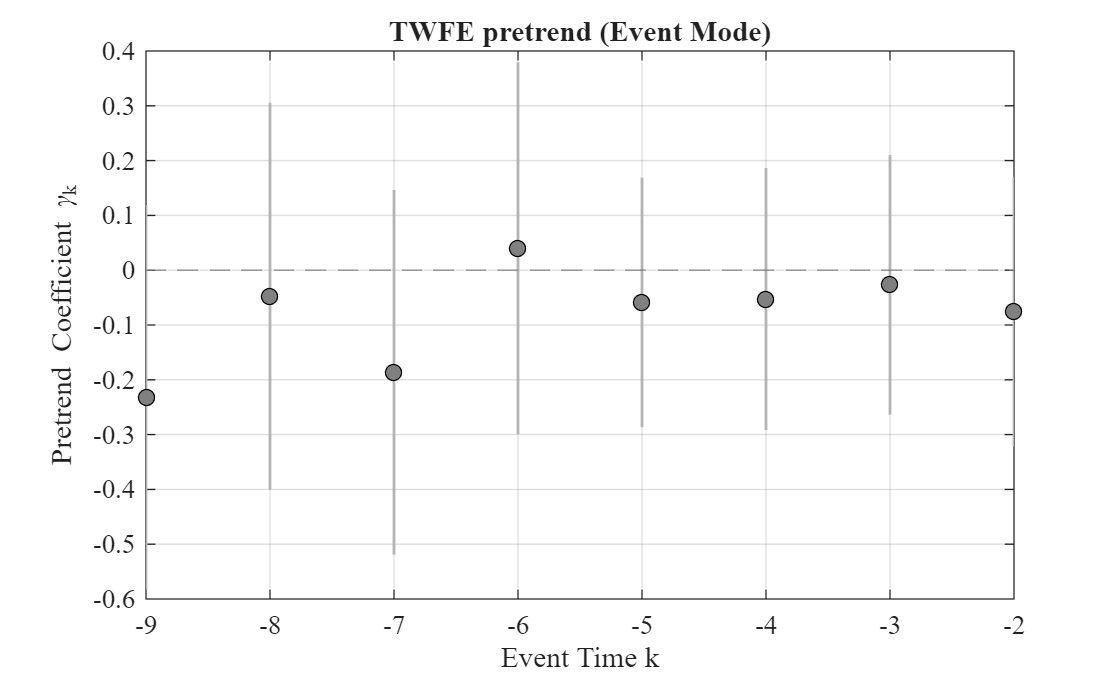

res = did.fit("twfe", ds, "preTrend", true, "preTrendMode", "event", "details", true);

**Modes (`preTrendMode`): **The estimator supports four specific modes for constructing the pre-trend test.

#### Options and Parameters

**baseline**: Valid for "event" mode. Defines the reference period (event time $k$) that is normalized to zero (omitted from estimation).

- -1 (default): Omit the period immediately before treatment ($k=-1$).

- -Inf: Automatically omit the *earliest* event time present in the sample ( $\min(k)$). Useful when you want to estimate the coefficient for $k=-1$ to test for anticipation/Ashenfelter's dip directly.

- NaN: Defaults to `-1`.

Example:

% Drop the very first lead (e.g. k=-10) to test k=-1

% did.fit(..., "preTrendMode", "event", "baseline", -Inf)

**preStart / preEnd**: Valid for all modes. Manually restricts the calendar time window used for the diagnostic test. If not provided (`NaN`), the estimator automatically determines the relevant window based on the mode and data.

- preStart: Start year/period (e.g., 2000).

- preEnd: End year/period (e.g., 2009).

Example:

% Focus pre-trend test only on the window [2005, 2010]

% did.fit(..., "preStart", 2005, "preEnd", 2010)

**TimeEffects**: Valid for all modes. Default: *true*. Controls whether Time Fixed Effects ($\lambda_t$) are included in the diagnostic regression.

- true: Include Time FEs (Standard TWFE specification).

- false: Include Unit FEs only.

Output Interpretation

- The *res.summaryTable* will contain the estimated coefficients.

- Event Mode: Coefficients named "Event k=-2", "Event k=-3", etc.

-         A significant coefficient suggests a deviation from parallel trends at that specific time relative to the baseline.

- Pooled Modes: Coefficients named "Interaction" or similar.

-         A significant coefficient indicates a systematic linear divergence trend.

**Joint Test**: The output struct also contains a joint F-test for the null hypothesis that *all* pre-trend coefficients are simultaneously zero.

For example, with "preTrendMode="event

  [absorbAPM] iter    1: relChange = 1.033e+00
  [absorbAPM] CONVERGED at iter 11 (relChange 3.716e-09 < tol 1.0e-08)
[TWFE pretrend event] 8 leads estimated (baseline k=-1 excluded).
[TWFE pretrend] Mode: event
  Pre window: [1, 15]
[TWFE pretrend] Standard errors clustered by gVar 
[TWFE pretrend] Pretrend coefficients (isTreated × pre_t):
  8×6 table

        Name        Estimate        SE        tStat       pValue     Nobs
    ____________    _________    ________    ________    ________    ____

    "Event k=-9"     -0.23187    0.047218     -4.9106    0.039056    5882
    "Event k=-8"    -0.047396    0.041417     -1.1444     0.37096    5882
    "Event k=-7"     -0.18627    0.038764     -4.8052    0.040684    5882
   

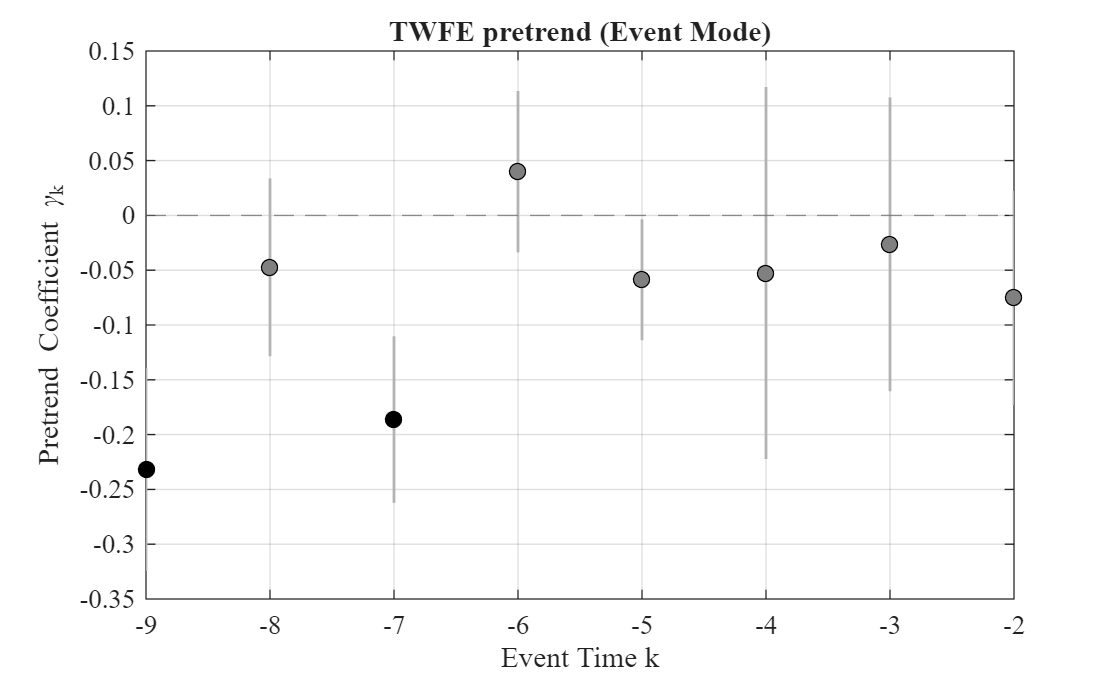

% Check pre-trends in event-time
res = did.fit("twfe", ds, ...
            "preTrend", true, ...
            "preTrendMode", "event", ...
            "baseline", -Inf, ... % <--- Auto-drop min(k)
            Covariates = ["x1","x2"], ...
            vcov       = "clustered", ...
            clusters   = "gVar", ...
            details=true, Display=true);

### IV.3    Placebo Treatment

--- tbd ---

### IV.4    Extrapolation of Parallel Trends (Honest DID)

#### Overview

The honest parallel trends diagnostic by Rambachan/Roth (2023) asks a simple question: "*Given what we see in the pre-treatment periods, how much could violations of parallel trends distort our estimated treatment effects in the post-periods?". T*he answer will be approximated by using the standard errors and a 95% confidence band as a starting point to take sampling bias into account. 

Note that if the average post-treatment event effects are not statistically significant from zero, running the sensitivity analysis is not informative and will not be conducted. 

Three different methods to test for the sensitivity against parallel trends deviation are implemented, but note that, at the moment, this analysis is only supported for the Callaway/Sant'Anna estimator CS:

**Relative Magnitude (RM)**

*DeltaType="RM"*: The RM approach restricts how much the *post-treatment bias* is allowed to move from period to period, *relative* to what we see in the pre-treatment period. Intuition:

- In the pre-period, we let the (unobserved) bias process wiggle around within the confidence bands of the pre-event coefficients. From this we infer how large the *worst* pre-period change in the bias could be from one period to the next.

- Call this worst pre-period change $B_{\max}$. RM then assumes that, after treatment starts, the bias cannot change more violently than M times this pre-period benchmark.

So the sensitivity parameter M has a direct interpretation:

- M=1: post-treatment bias can be at most as “rough” as in the pre-period.

- M=2: post-treatment bias can change up to twice as fast as the worst pre-period change, and so on.

By increasing M, we ask how robust our conclusions are if we allow for increasingly unstable bias dynamics after treatment, compared to what we observed pre-treatment.

**Smooth Drift (SD)**

*DeltaType="SD"*: A smooth non-linear distortion function is applied over event time to analyze the maximal feasible distortion to maintain statistical significance of the overall aggregated event time coefficient. One determines confidence sets that allow the maximum post-treatment violation of parallel trends to be up to M times larger than the maximum pre-treatment violation for different values of M.   

The SD specification assumes that any violation of parallel trends evolves *smoothly* over time. In practice, this means we do not allow the bias to have very sharp kinks from one period to the next: its curvature is bounded. The sensitivity parameter MMM controls how much curvature we permit.

- Small M bias must be very smooth → honest intervals are tight.

- Large M: we allow more wiggly bias paths → honest intervals widen.

SD does *not* use information from the pre-period to calibrate the size of the bias; it only restricts how “bendy” the bias path can be.

**Smooth Drift & Relative Magnitudes (SDRM)**

*DeltaType="SDRM"*: The SDRM approach combines two types of restrictions:

- Smooth Drift (SD)**:** the bias process cannot have arbitrarily sharp curvature over time (second differences are bounded). This rules out extremely “spiky” behaviour in any direction.

- Relative Magnitudes (RM)**:** as above, post-treatment changes in the bias cannot be more than M times as large as the worst change we could have had in the pre-period.

SDRM therefore gives an *intersection* of both sets of assumptions: we only allow bias paths that are (i) reasonably smooth over time and (ii) not much more volatile after treatment than before.

Interpretation in practice:

- Compared to SD alone, SDRM additionally uses information from the pre-trend to calibrate how large post-treatment changes in bias are allowed to be.

- Compared to RM alone, SDRM rules out very “kinked” or erratic paths that would otherwise still satisfy the relative-magnitude bound.

When you look at the SDRM honest intervals as you increase M, you are simultaneously relaxing both curvature and volatility restrictions: higher M means you are willing to tolerate both rougher and somewhat less smooth bias paths than those suggested by the pre-period data.

#### Usage Workflow

Honest DiD is a post-estimation diagnostic. You generally apply it *after* running an event study (e.g., Callaway-Sant'Anna).

1. Run an Event Study: First, estimate a dynamic difference-in-differences model. The result object must contain event-study coefficients.

% Estimate Callaway-Sant'Anna Event Study

resCS = did.fit("cs", T, 'yVar', 'y', 'dVar', 'D', 'idVar', 'id', 'timeVar', 'time');

2. Initialize Honest DiD: Use the *fromFit* static method to automatically extract coefficients ($\hat{\beta}$) and the covariance matrix ($\Sigma$) from the result.

% Initialize diagnostics

    hd = did.diagnostics.HonestDiD.fromFit(resCS);

3. Run Sensitivity Analysis (`fit`): Calculate the confidence intervals over a grid of possible violation magnitudes$M$.

- Target: The average post-treatment effect

- M: Vector of violation magnitudes to test

Code example: out = hd.fit('Target', "average", 'M', 0:0.1:2, 'Alpha',   0.05);

4. Visualize (plot): Generate the sensitivity plot, which shows the Confidence Interval as a function of$M$.

% Plot the FLCI

Code example:  hd.plot(out);

The plot will show:

- X-axis: The magnitude of potential trend violation ($M$).

- Y-axis: The estimated effect with 95% Confidence Interval.

- Breakdown Value: The value of $M$ where the CI crosses zero (if applicable).

#### Parameters (*fit* options)

Manual Initialization: If you have coefficients from an external estimator, you can initialize manually:

- beta: (NumPre + NumPost) x 1 vector of coefficients

- sigma: Covariance matrix

Code example:     *hd = did.diagnostics.HonestDiD(beta, sigma, numPre, numPost);*

*Code example for limited post period: *`did.diagnostics.cs_honest_pt(resCS, "L_vec", [0.5; 0.5; 0], ...)`

- `This takes assumed 3 post periods and weighs the average to ignore the third post-period  `

**Example for Parallel trends Sensitivity (Rambachan/Roth 2023)**

We rely on the same data as simulated before (see Section II.1), with "constantTime" treatment of three treated cohort at periods 4, 5 and 7 (out of 12 years) and increasing ATTs over time per cohort of 2, 3, and 4, respectively.

Then we run the Callaway/Sant'Anna estimator:

% --- Fit CS estimator --------------------------------------
resCS = did.fit("cs", ds, ...
    Comparison="never", Delta=0, Approach="dr", Covariates=["x1","x2"], ...
    Seed=42, SEMethod="multiplier", B=100, Display=false);
resCS.Aggregates.es

ans = 18×7 table
    e     Estimate       SE         tStat      pValue       LB         UB   
    __    _________    _______    _________    ______    ________    _______

    -9    -0.055099    0.27033     -0.20383     0.88     -0.81912    0.70892
    -8     -0.35586    0.24897      -1.4293     0.17      -1.0595     0.3478
    -7     -0.13482    0.26128     -0.51599     0.56     -0.87327    0.60363
    -6       0.2056    0.18886       1.0886     0.26     -0.32819    0.73939
    -5    -0.069789     0.2339     -0.29837     0.76     -0.73085    0.59127
    -4    -0.018206    0.18612    -0.097817     0.92     -0.54424    0.50783
    -3      0.10245    0.17004      0.60251     0.52     -0.37814    0.58304
    -2     0.094279    0.17759      0.53088     0.5

First we have a look at a smooth drift analysis. We allow for violations of parallel trends summarized by the curvature parameter M in the “second-difference” restriction $|\Delta^2\delta_e|\le M$, where $\delta _e$ is the deviation from parallel trends at event time *e*. 

The event-study estimates from CS are fed into the honest parallel trends (*cs_honest_pt*) routine and iterate over distortion values for parallel trends.

[cs_honest_pt] Using CS event-study with 9 pre and 9 post periods.
  Pre e in [-9, ..., -1]; Post e in [0, ..., 8].
  Target = avgPost, DeltaType = SD, PreBand=1.960.
  [honest_pt] Anchoring delta(9) = 0 (Reference Period, e=-1)
  [honest_pt] Anchoring delta(8) = 0 (Pre-Reference, e=-2) to fix SD trend.
[honest_pt] Scanning curvature grid with 300 values of M.
  M=0.010: θ ∈ [2.5131, 2.8798]
  M=0.020: θ ∈ [2.3298, 3.0631]
  M=0.030: θ ∈ [2.1464, 3.2464]
  M=0.040: θ ∈ [1.9631, 3.4298]
  M=0.050: θ ∈ [1.7798, 3.6131]
  M=0.060: θ ∈ [1.5964, 3.7964]
  M=0.070: θ ∈ [1.4131, 3.9798]
  M=0.080: θ ∈ [1.2298, 4.1631]
  M=0.090: θ ∈ [1.0464, 4.3464]
  M=0.100: θ ∈ [0.8631, 4.5298]
  M=0.110: θ ∈ [0.6798, 4.7131]
  M=0.120: θ ∈ [0.4964, 4.8964]
  M=0.130: θ ∈ [0.3131, 5.0798]
  M=0.140: θ ∈ [0.1298, 5.2631]
  M=0.150: θ ∈ [-0.0536, 5.4464]
[honest_pt] Zero enters honest interval at M=0.1500. Stopping grid here.
[honest_pt] Smallest feasible M (pre-trends compatible): M_feas = 0.0100, θ ∈ [2.51

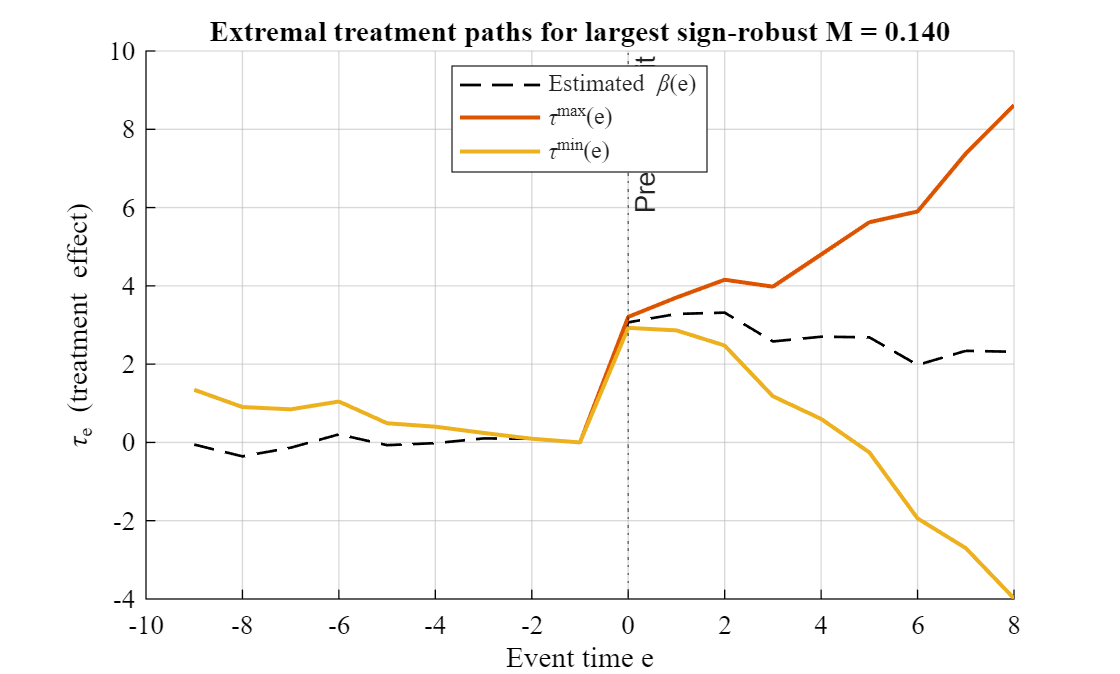

% --- Honest PT with a reasonably fine M grid SMOOTH DRIFT -------------------------
honPT = did.diagnostics.cs_honest_pt(resCS, ...
    DeltaType = "SD", ...
    Target    = "avgPost", ...
    PreBand   = 1.96, ...   % 95% CI band around pre β
    Verbose   = true);

### IV.5    Synthetic DiD

Arkhangelsky et al. (2021) study synthetic difference-in-differences (SDID) methods, which try to generate parallel trends by reweighting units to match their pre-exposure trends. 

- Unit Weights ($\omega$): Reweight control units to match the pre-treatment average of the treated unit (similar to Synthetic Control).

- Time Weights ($\lambda$): Reweight pre-treatment periods to match the average post-treatment properties (balancing time-varying confounders).

- Double Doubly Robust: The estimator applies a DID on these reweighted terms.

                                                                           
$$ \hat{\tau}^{SDID} = (\bar{Y}_{tr,post} - \bar{Y}_{tr,pre}^{\lambda}) - (\bar{Y}_{co,post}^{\omega} - \bar{Y}_{co,pre}^{\omega,\lambda}) 
$$


Note the SDID is another specific estimator developed by Arkhangelsky et al. (2021), as it conducts DiD analysis with unit and time-weighting, which cannot be achieved with one-dimensional unit weighting like in CEM):

Unit Weights ($\omega$) vs Time Weights ($\lambda$):

- Other estiamtors (like weighted BJS) only use unit weights ($\omega$). One could conceptually calculate Synthetic Control weights and pass them to BJS. This would improve the "Unit Fixed Effects" by emphasizing control units that look like treated units.

- SDID adds Time Weights ($\lambda$). It re-weights the pre-treatment periods to make them look like the post-treatment periods. This removes time-varying bias (drift) that standard Time Fixed Effects ($\gamma_t$) cannot capture if the parallel trends assumption is violated in complex ways. BJS has no mechanism to accept or use "Time Weights" for the imputation step.

Imputation vs Double-Difference:

- BJS imputes the counterfactual as: $\hat{Y}(0)_{it} = \hat{\alpha}_i + \hat{\gamma}_t$ .

- SDID calculates the effect as a double-difference of weighted means:

                    
$$$$ \hat{\tau} = (\bar{Y}{post}^{tr} - \bar{Y}{pre(\lambda)}^{tr}) - (\bar{Y}{post(\omega)}^{co} - \bar{Y}{pre(\lambda,\omega)}^{co}) $$$$


- This structure effectively performs a "local" Difference-in-Differences using the optimized weights, which is different from scanning the whole panel to estimate global Fixed Effects like BJS does.

**Syntax**

To use SDID in the toolbox, specify "SDID" as the method in did.fit.

    results = did.fit("SDID", T, 'yVar', 'y', 'dVar', 'D', 'idVar', 'id', 'timeVar', 'time');

The estimator automatically:

- Pivots the data to wide format ($N \times T$).

- Calculates unit weights ($\omega$) and time weights ($\lambda$).

- Computes standard errors via placebo inference.

**Optional Parameters**

You can customize the estimation via name-value arguments:

#### Example

We first generate data with 50% of controls having a trend diverging from the treatment group

data = did.genDIDdata(10, 200, 0.25, ...
    "treatType", "constantTime", ...
    "cohortTimes", [3,5,7], ...
    "meanError", 0, "errorStd", 0.5, ...
    "preTrendType", "divergentControls", ...
    "preTrendSd", 0.2, ...            % Add variance (the key to the "distributed" look)
    "preTrendMeanTreated", 0.5, ...   % Treated units (and "Good" controls)
    "preTrendMeanControl", -0.2);     % "Bad" divergent controls


 % generate data object  
 ds = did.Dataset.fromTable(data, ...
        "idVar", "id", "timeVar", "time", "dVar", "D", "yVar", "y", ...
        "Display", true);


[DataDesc] Units = 200 | Periods = 10 | Nobs = 2000 | Balanced Units = 200 (100.0%)
[DataDesc] Ever-treated = 58 (29.0%) | Never-treated = 142 (71.0%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "3"           18       0.09         0                   0                      3       
        "5"           20        0.1         0                   0                      5       
        "7"           20        0.1         0                   0                      7       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean  

  % fit BJS (unweighted / biased)
  res_BJS = did.fit("BJS",ds);


[BJS Optimized] N_unt=1656, N_trt_ident=344. Overall ATT: 3.8525 (SE 0.2467)

[BJS] Estimates (SE=LOO, Boot=199)
        Name         Estimate      SE       tStat       pValue  
    _____________    ________    _______    ______    __________

    "ATT_overall"     3.8525     0.24674    15.614     5.861e-55
    "ATT_k=0"         3.2334     0.17808    18.158    1.1192e-73
    "ATT_k=1"         3.6332     0.21142    17.185    3.4458e-66
    "ATT_k=2"         3.9829      0.2508    15.881    8.5946e-57
    "ATT_k=3"         4.2374      0.2888    14.673    9.6417e-49
    "ATT_k=4"         4.0134     0.34142    11.755    6.6447e-32
    "ATT_k=5"         4.1454     0.37698    10.997     3.972e-28
    "ATT_k=6"         3.8042     0.45284    8.4006    4.4403e-17
    "ATT_k=7"         3.9845     0.54031    7.3744    1.6511e-13


  % Fit SDID
  % Use Placebo inference for validity
  res_sdid = did.fit("sdid", ds, ...
        "Display", true, ...
        "SEMethod", "Placebo", ...
        "B", 50, ...             % Low B (number of bootstraps) for speed 
        "UseParallel", false);   % Avoid nested parfor

     Name     Estimate       SE       tStat       pValue   
    ______    ________    ________    ______    ___________

    "SDID"     2.7038     0.077647    34.823    1.1105e-265

Aggregated over 3 cohorts.
[SDID] Weights: SDID
[SDID] Aggregate Estimate: 2.7038 (SE: 0.0776, t: 34.82, p: 0.0000)

[SDID] Cohort Estimates:
    Cohort    N     Estimate      SE       tStat     pValue    Weight
    ______    __    ________    _______    ______    ______    ______

     "3"      18     2.2509      0.1153    19.523      0        144  
     "5"      20     2.8131     0.13515    20.815      0 

As the true ATT is equal to 2, one can see that a simple BJS estimate would be heavily biased due to the divergent trends in the control group. However depending on the data structure one can see that the bias doesn't fully disappear with SDID, though it strongly reduces.

For a deeper analysis, see the example file "Simulation_SDID.m", which conducts MC simulation to assess statistical properties of SDID.

Let's plot the weights across units and time to illsutrate the time and unit weighting in this case (of course, this is only possible as we know the true parameters of the simulation, not with real-world data).

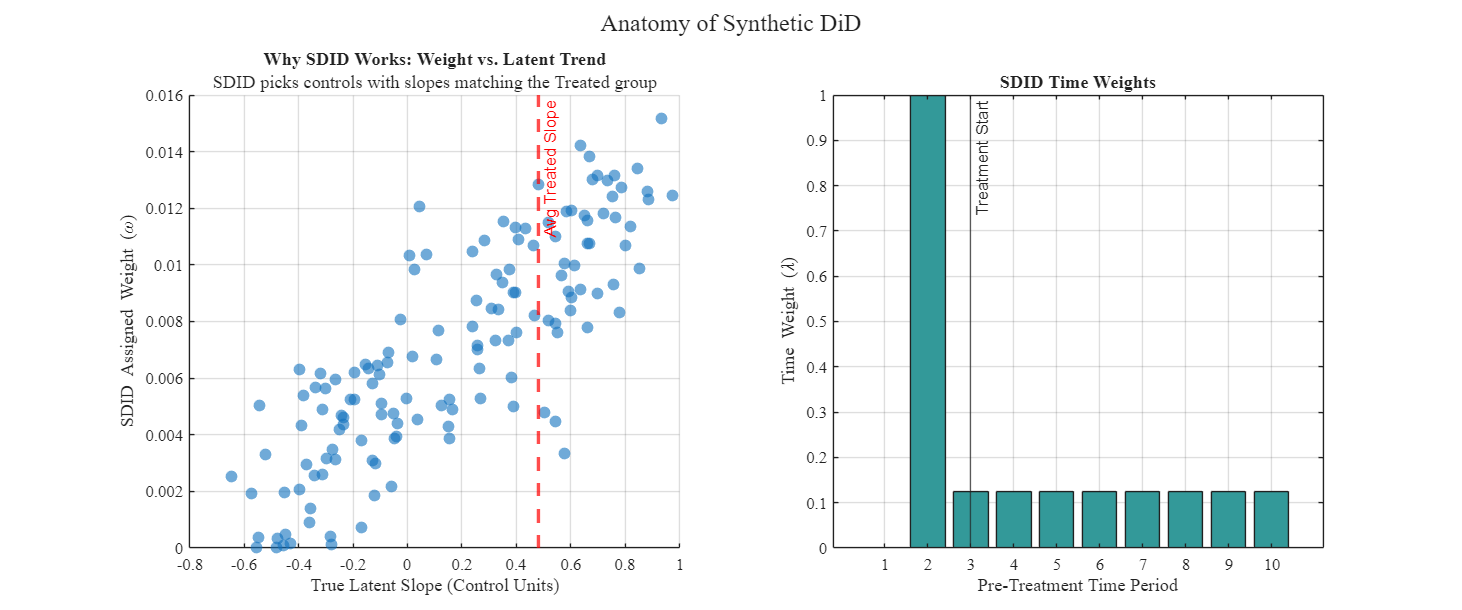

% -------------------------------------------------------------------------
% SDID provides unit weights (omega).
% Hypothesis: SDID should assign HIGH weights to Control units that, by chance,
% have steep slopes (similar to Treated), and LOW weights to flat controls.

% Extract Weights for the first (and only) cohort
% Since we have simultaneous adoption here for illustration, weights are simple.
% SDID.fit for staggered aggregates, but we can look at the first cohort details.
cDetails = res_sdid.Details.Cohorts(1);

% Get Control indices and their weights
co_idx = cDetails.Controls;  % Indices in the Y matrix
weights = cDetails.Omega;    % Vector of weights summing to 1

% Get the TRUE slopes for these control units

[~, uniqueIdx] = unique(data.id);
is_treated  = data.everTreated(uniqueIdx) == 1;
% Sort by ID to match did.Dataset internal ordering if needed, but unique returns in order of appearance usually.
% Let's be safe: sort uniqueIdx
% The simulation generates IDs 1..N sequentially, so unique is safe.
true_slopes = data.latent_slope(uniqueIdx);
co_slopes = true_slopes(co_idx);

% Plot: Weight vs True Slope
figure('Name','SDID Unit Weights Analysis','Color','w','Position',[100 100 1200 500]);

subplot(1, 2, 1);
scatter(co_slopes, weights, 50, 'filled', 'MarkerFaceAlpha', 0.6);
xlabel('True Latent Slope (Control Units)');
ylabel('SDID Assigned Weight (\omega)');
title('Why SDID Works: Weight vs. Latent Trend');
grid on;
xline(mean(true_slopes(is_treated)), '--r', 'Avg Treated Slope', 'LineWidth', 2);
subtitle('SDID picks controls with slopes matching the Treated group');

% -------------------------------------------------------------------------
% Interpretation of Time Weights (Lambda)
% -------------------------------------------------------------------------
% Time weights (\lambda) emphasize pre-treatment periods that best predict
% the post-treatment average.
% In a pure linear trend case, this might be balanced.

lambda = cDetails.Lambda;
% Lambda corresponds to the pre-treatment periods used in estimation.
% Length should be G-1?
% Let's make x-axis dynamic based on Lambda length.
pre_times = (1:length(lambda))';

subplot(1, 2, 2);
bar(pre_times, lambda, 'FaceColor', [0.2 0.6 0.6]);
xlabel('Pre-Treatment Time Period');
ylabel('Time Weight (\lambda)');
title('SDID Time Weights');
grid on;
xline(cDetails.G, '-', 'Treatment Start');

sgtitle('Anatomy of Synthetic DiD');

As the true ATT is equal to 2, one can see that a simple BJS estimate would be heavily biased due to the divergent trends in the control group. However depending on the data structure one can see that the bias doesn't fully disappear with SDID, though it strongly reduces.

For a deeper analysis, see the example file "Simulation_SDID.m", which conducts MC simulation to assess statistical properties of SDID.

### IV.5    Coarsened Exact matching (CEM)

Coarsened Exact Matching (CEM) significantly reduces model dependence and bias in observational studies by matching treated and control units on "coarsened" covariates, matching treated and control units based on *coarsened* versions of covariates rather than their exact raw values.

The toolbox implementation:

- Coarsens specified covariates into bins (user-defined or default).

- Matches units exactly within these coarse strata.

- Prunes mismatched observations (zero weight).

- Weights the remaining control units to match the distribution of the treated units.

- Estimates the ATT using a *Weighted Two-Way Fixed Effects* (TWFE) regression on the matched sample.

 Key Advantages

- Balance: Ensures groups are comparable on observable characteristics.

- Robustness: When `Robust=true` is used, the final regression includes Covariate × Time interactions ($X_i \cdot t$), providing "double robustness" against differential trends driven by those covariates.

CEM is particularly useful under the following conditions:

Observational (Non-Randomized) Data

- Treatment assignment is not random.

- Confounding is a concern.

- Randomized controlled trials are infeasible.

Moderate to Large Sample Sizes

- Enough observations exist to populate coarsened strata with both treated and control units.

- Very small datasets risk excessive pruning.

Covariates with Clear Substantive Meaning

- Variables can be meaningfully coarsened (e.g., age groups, income brackets, education levels).

- Strong domain knowledge exists to justify binning choices.

Imbalance in Covariate Distributions

- Significant pre-treatment imbalance between treated and control groups.

- CEM directly targets imbalance rather than modeling it indirectly.

**Note**: Unlike propensity score matching, CEM does not rely on modeling the treatment assignment mechanism.

#### Syntax

To use the CEM estimator, call *did.fit* with the method "CEM".

In addition to the standard data mapping arguments (`idVar`, `timeVar`, `yVar`, `dVar`), the CEM estimator accepts:

#### Output Structure

The result struct contains:

- tau: The estimated Average Treatment Effect on the Treated (ATT).

- se: Standard Error of the estimate.

- MatchedN: Number of units remaining after pruning.

- OriginalN: Total number of original units.

- Model: The underlying `LinearModel` object from `fitlm` (useful for extracting weights or residuals).

- res.Model.Variables.Weight: The generated CEM weights.

#### Examples

**Standard CEM**: Basic matching on `gdp` and `population`, using 5 bins (default).

% Basic CEM

% res = did.fit("CEM", T, 'idVar', "country_id", 'timeVar', "year", 'yVar', "inflation", 'dVar', "training_program", 'Covariates', ["gdp", "population"], ...
%     'nBins', 5);

 **Robust CEM (Recommended)**: Matching on `gdp` with finer bins (10), plus "Robust" adjustment to handle remaining trend differences.

% Robust CEM (Doubly Robust)

% res = did.fit("CEM", T, 'idVar', "country_id", 'timeVar', "year", 'yVar', "inflation", ...
%     'dVar', "training_program",  'Covariates', ["gdp"], 'nBins', 10,...
%     'Robust', true);  % <--- Adds gdp*time interaction
% fprintf('Robust ATT: %.4f\n', res.tau);

**Extracting Weights for Other Estimators**

You can use the weights generated by CEM to feed into other estimators (*TWFE* or *BJS*).

% 1. Run CEM to get weights

% res_cem = did.fit("CEM",ds,'Covariates', ["gdp"]);
%     % 2. Extract Matched Data and Weights
% T_matched = res_cem.Model.Variables; % Table with weights
% weights   = T_matched.Weight;
% % 3. Use in Weighted BJS
% res_bjs = did.estimators.bjs_imputation(T_matched, ...
%     'idVar','id', 'timeVar','year', 'yVar','inflation', 'dVar','d', ...
%     'Weights', weights, 'Covariates', ["gdp_trend"]); % optional trend

#### Worked Example

We simulates the selection on observables problem, Coarsened Exact Matching (CEM) is designed to solve. It does this by creating a dependency between covariates ($X$), treatment assignment ($D$), and the outcome ($Y$).

% gen Data with selectivity for the treated on observable characteristic 
T = did.genDIDdata(10, 200, 0.5, ...
        'xNum', 1, ...
        'SelectionBias', 1.0, ...
        'TrendEffectX', 0.5, ...
        'treatType',    "constant", ...
        'startPeriod',  4, ...
        'endPeriod',    9, ...
        'ATT',          2, ...
        'xTimeStd', 0.1, ...
        'xShockStd', 0.5, ...
        'errorStd', 0.5);

% generate data object ds
ds = did.Dataset.fromTable(T, ...
        "idVar", "id", "timeVar", "time", "dVar", "D", "yVar", "y", ...
        "Display", true);


[DataDesc] Units = 200 | Periods = 10 | Nobs = 2000 | Balanced Units = 200 (100.0%)
[DataDesc] Ever-treated = 103 (51.5%) | Never-treated = 97 (48.5%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "4"           103      0.515        0                   0                      4       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean       SD        Min        P25       Median     P75      Max  
    ____   


% Naive TWFE
res_twfe = did.fit("TWFE", ds, "Display", true);

[TWFE] DepVar: y
[TWFE] Obs: 2000 | Units: 200 | Time: 10
[TWFE] Within-R2: 0.1743
[TWFE] Fixed Effects: Unit, Time
[TWFE] Standard errors clustered by id 
  1×5 table

    Name    Estimate      SE       tStat       pValue  
    ____    ________    _______    ______    __________

    "D"      3.9861     0.32393    12.306    3.0194e-26



% CEM estimation
res_cem_base = did.fit("CEM", ds, "Covariates", "x1", "nBins", 10, "Robust", false, "Display", true);


--------------------------------------------------------------
CEM Matching Results
Matched Units: 189 (Original: 200)
Treated: 95 | Control: 94
--------------------------------------------------------------

[DataDesc] Units = 189 | Periods = 10 | Nobs = 1890 | Balanced Units = 189 (100.0%)
[DataDesc] Ever-treated = 95 (50.3%) | Never-treated = 94 (49.7%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units     Share     N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _______    _________    _______________________    _______________

        "4"           95       0.50265        0                   0                      4       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       <

% with covariate
res_cem = did.fit("CEM", ds, ...
    "Covariates", "x1", ...
    "nBins",      10, ...
    "Robust",     true, ...
    "Display",    true);


--------------------------------------------------------------
CEM Matching Results
Matched Units: 189 (Original: 200)
Treated: 95 | Control: 94
--------------------------------------------------------------

[DataDesc] Units = 189 | Periods = 10 | Nobs = 1890 | Balanced Units = 189 (100.0%)
[DataDesc] Ever-treated = 95 (50.3%) | Never-treated = 94 (49.7%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units     Share     N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _______    _________    _______________________    _______________

        "4"           95       0.50265        0                   0                      4       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       <

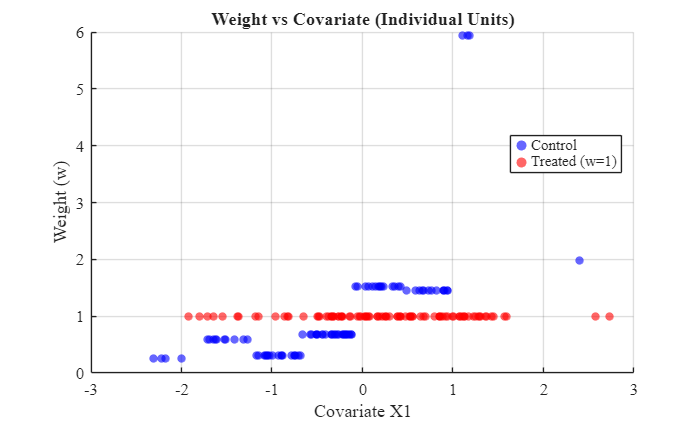

% illustrate the weights
w_ids = res_cem.MatchedIDs;
w_vec = res_cem.WeightsVector;


[uIDs, idx] = unique(w_ids);
uWeights = w_vec(idx);

% Find indices in T to get Treatment Status (from everTreated)
[Lia, Locb] = ismember(uIDs, T.id);
uTreated = T.everTreated(Locb);

% Extract X for scatter plot
uX       = T.x1(Locb);
uX_tr    = uX(uTreated==1);
uX_co    = uX(uTreated==0);

w_tr     = uWeights(uTreated==1);
w_co     = uWeights(uTreated==0);

figure('Name', 'CEM Weight Distribution', 'Color', 'w');


% Scatter Plot: Weight vs X
scatter(uX_co, w_co, 25, 'b', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(uX_tr, w_tr, 25, 'r', 'filled', 'MarkerFaceAlpha', 0.6);

title('Weight vs Covariate (Individual Units)');
ylabel('Weight (w)');
xlabel('Covariate X1');
legend('Control', 'Treated (w=1)', 'Location', 'best');
grid on;

See "*cem_MonterCarlo_staggeredTreatment.m*" for an in-depth MC analysis of biases and CEM in a staggered DiD setting.

## V    Usage Guidelines and Overview

## VI    References

- Arkhangelsky, D. /  Athey, S. / Hirshberg, D. / Imbens, G. /  Wager, S. (2021): Synthetic Difference-in-Differences, American Economic Review 111, 4088–4118.    

- Baker, A. / Larcker, D. / Wang, C. (2022). How Much Should We Trust Staggered Difference-In-Differences Estimates?, Journal of Financial Economics, 144, 370–395.

- Baker, A. / Callaway, B. / Cunningham, S. / Goodman-Bacon, A. / Sant'Anna, P. (2025): Difference-in-Differences Design: A Practitioners Guide, Journal of Economic Literature (forthcoming).

- Borusyak, K. / Jaravel, X. / Spiess, J. (2024). Revisiting Event-Study Designs: Robust and Efficient Estimation, Review of Economic Studies, 00, 1–33.

- Deb, P. / Norton, E. / Wooldridge, J. /  Zabel, J. E. (2025) :Aggregating Average Treatment Effects on the Treated in Difference-in-Differences Models, NBER Working Paper No. 34331, October 2025. 

- Callaway, B. / Sant'Anna, P. (2021). Difference-in-Differences with Multiple Time Periods. Journal of Econometrics, 225(2), 200-230.

- de Chaisemartin, C., & D'Haultfœuille, X. (2020). Two-Way Fixed Effects Estimators with Heterogeneous Treatment Effects, American Economic Review 110(9), 2964-2996.

- Chernozhukov et al. (2018): Double/debiased machine learning for treatment and structural parameters, Econometrics Journal 21, 1-68.

- Goodman-Bacon, A. (2021). Difference-in-differences with variation in treatment timing, Journal of Econometrics, 225(2), 254-277.

- Rambachan, A. / Roth, J. (2023): A More Credible Approach to Parallel Trends, Review of Economic Studies 90, 2555-2591. 

- Sant’Anna, P. /  Xu, Q. (2025): Difference-in-Differences with Compositional Changes*, *Arxiv 2304.13925.

- Sant'Anna, P. / Zhao, J. (2020): Doubly robust difference-in-differences estimators, *Journal of Econometrics*, *219*(1), 101-122. 

- Sun, L. / Abraham, S. (2021): Estimating dynamic treatment effects in event studies with heterogeneous treatment effects, Journal of Econometrics 225, 175-199.

- Wooldridge, J. (2021). Two-Way Fixed Effects, the Two-Way Mundlak Regression, and Event Study Estimators. Working Paper.

## Appendix:    List of Worked Examples

The `did-toolbox` includes several example scripts in the `Examples` folder to demonstrate real-world usage and specific methodologies.

### 1. Real-World Applications

**Example_Medicaid.m**

Medicaid Expansion (Baker et al. 2025): An analysis of the "Medicaid Expansion" dataset, build on the data provided in the Baker et al. (2025) replication package. using the Callaway & Sant'Anna (CS) estimator.

Key Features:

-       Loading and preparing real data.

-       Estimating dynamic Group-Time ATTs.

-       Event-study plotting.

**Example_Quota_Analysis.m**

Gender Quotas and motherly birth mortality (Synthetic DiD)

Key Features:

-   Application of SDID to a policy evaluation question.

-   Comparison of Standard DiD vs Synthetic DiD.

**Example_HonestDiD.m**

Sensitivity Analysis (Honest DiD): Demonstrates how to perform Rambachan & Roth's sensitivity analysis on the Medicaid data.

Workflow:

    1. Estimate Event Study using CS.

    2. Extract coefficients and covariance.

    3. Compute "Honest" Confidence Intervals for various violations of parallel trends ($M$).

**RealWorld_Example_DiDToolbox.mlx**

A MATLAB Live Script illustrating using the Matlab DiD Toolbox in a real world application - a test of the so-called "Castle Doctrine" (a change in U.S. self-defense law) on the homicides before and after the change in law. This analysis is based on the example in Scott Cunningham's diff-in-diff blog and the study by *Cheng & Hoekstra (2013)*.

### 2. Methodology-Specific Examples

**Example_GenDID_Showcase**

Illustrates basically all possibilties to use genDIDdata with different characteristics.

**Example_SDID.m**

Inspecting SDID Weights: Focuses on understanding how Synthetic DiD constructs its counterfactual.

Key Features:

-   Extracting Unit Weights ($\omega$) and Time Weights ($\lambda$).

-   Visualizing which control units contribute most to the synthetic control.

**Simulate_SDID**

A Monte Carlo simulation to compare the bias of TWFE versus synthetic DID (SDID)

**Replicate_Stata_HonestDiD.m**

Cross-Software Validation: A script designed to replicate results from the Stata *honestdid* package to ensure the Matlab toolbox implementation is correct.

**MC_Simulation_TWFE_Pretrends**

Monte Carlo simulation testing for pretrend differences between treated and controls using the toolbox's pre-trend diagnostic. It provides an analysis of both size and power of the tests.

Scenario 1: H0 (Null Hypothesis)

- Structure: Constant treatment effect, Staggered adoption (cohorts at t=8, 14).

- Trend: Parallel trends hold perfectly (preTrendType="none").

- Metric: Size (Rejection Rate). Since there is no violation, this should be close to the nominal level (0.05).

Scenario 2: H1 (Alternative Hypothesis)

- Structure: Same as H0.

- Trend: Violation! Treated units have a linear upward trend (slope = 0.1) that Control units do not.

- Metric: Power (Rejection Rate). We want this to be high (> 0.05), indicating the test successfully detects the violation.

The test show valid size (~5% rejection when H0 is true), but for short pre-periods a weak pwoer to detect violations of parallel trends.

### 3. Validation & Testing

**validate_toolbox_cem.m**

Topic: Coarse Exact Matching (CEM): CEM is matching algorithm where unit characteristics are matched with a possible imprecision, i.e. one does not require exactly the same characteristic between matched units but defines buckets of characteristic proximity which are then used for matching. The example conducts Monte Carlo simulationto validate the CEM estimator.

Key Features:

-   Generating data with selection bias and confounding trends.

-   Comparing Naive TWFE vs CEM-Weighted TWFE.

-   Generating Event Study and Covariate Balance plots.

**cem_MonteCarlo_staggeredTreatment.m**

Topic: Validation of coarse exact matching in the context of a staggered treatment of units. The Monte Carlo simulation compares simulated data with heterogeneous trends and selection bias, and then applies estimators with and without CEM.  

Estimators Compared:

-     TWFE

-     Wooldridge (Pooled): Fails due to Selection Bias.

-     Weighted Wooldridge: Improved but still biased in this DGP.

-     Weighted BJS (Imputation): Good performance (Unit FEs handle Selection Bias).

-     Weighted BJS + Trend Covariate: **Optimal** performance (Bias $\approx 0$).

Key Insight: Demonstrates the "Double Robustness" of combining weights (for balance/matching) with explicit trend variability modeling ($X\cdot t$). One ***should*** use the characteristic used for matching also as a covariate.

### 4. Other Resources

- *SimpleDIDAnalysis.mlx*: A simple live script, covering the basics of 2x2 DiD.